# ModSim Project 3 - Finding Optimal 3-Point Shot Angle

*Authors:* Lili Baker and Amit Kumar-Hermosillo

*Our Learning Objectives*:

- Practice scoping a model

- Transform physical specifications into a mathematical model

- Improve ability with physics

## Modeling Question

What launch angle of a 3-point shot in basketball produces the greatest margin of error? This is a design question as it seeks the optimal angle for a 3-point shot in basketball.

TODO: Add what our success metric is.

Finding the launch angle with the greatest margin of error will reveal which angle is most reliable when shooting from the 3-point line. From the persepctive of a baseketball player, it is important to know which angle will result in the greatest chance of earning points.

## Model

In order to answer the aforementioned modeling question, the launch angles will be swept. For each angle, the margin of error will be calculated by sweeping through the velocity range and determining if the shot was successful at each velocity value. In this sense, the margin of error refers to the percentage of velocities for the given angle at which the shot is successful. The maximum margin of error will then be deduced, and the corresponding angle will be returned as the optimal launch angle.

### Free Body Diagram

In order to determine the optimal angle, the trajectory of the basketball at each angle must be determined. Thus, the forces exerted upon the basketball must be defined, as seen in figure 1.

Figure 1. Free Body Diagram of Forces on Basketball

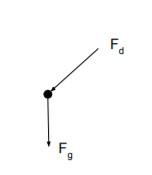

In figure 1, $F_d$ represents the force acting upon the basketball from drag in both the x- and y-direction, while $F_g$ represents the force acting upon the basketball from gravity. 

The force acting upon the basketball from drag is:


$$F_{d} = \frac{1}{2} C\rho Av^2\$$


In the above equation, *C* is the coefficient of drag of the basketball; $\rho$ is the density of air; *A* is the cross-sectional area of the basketball; and *v* is the velocity of the basketball.

The force acting upon the basketball from gravity is:


$$F_g = mg\$$


In the above equation, *g *is the value of acceleration due to gravity, while *m* is the mass of the basketball.

### Ordinary Differential Equations

#### Second Order Differential Equations

The motion of the basketball was broken down into x- and y-components. Therefore, the second order differential equations that illustrate the motion of the baketball are as follows.


$$\frac{d^2x}{dt^2}=\frac{F_{dx}}{m}\\
\frac{d^2y}{dt^2}=\frac{F_{dy}}{m}-g\$$


As seen above, the second derivative of position in the x-direction (or, rather, the acceleration in the x-direction) is equal to the force caused by drag in the x-direction divided by the mass of the basketball. Conversely, the second derivative of position in the y-direction is equal to the force caused by drag in the y-direction divided by the mass of the basketball, subtracted by acceleration due to gravity.

#### First Order Differential Equations

In order to simplify the modeling process, the above second order differential equations where changed into the following set of first order differential equations.

For $\frac{d^2x}{dt^2}=\frac{F_{dx}}{m}\
$:


$$\frac{dx}{dt}=v_x\\
\frac{dv_x}{dt}=\frac{F_{dx}}{m}\$$


Thus, the derivative of the x-position with respect to time is velocity in the x-direction. The derivative of the velocity in the x-direction is acceleration in the x-direction and, thus, the force caused by drag in the x-direction divided by the mass of the basketball.

For $\frac{d^2y}{dt^2}=\frac{F_{dy}}{m}-g\
$:


$$\frac{dy}{dt}=v_y\\
\frac{dv_y}{dt}=\frac{F_{dy}}{m}-g\$$


Thus, the derivative of the y-position with respect to time is velocity in the y-direction. The derivative of the velocity in the y-direction is acceleration in the y-direction and, thus, the force caused by drag in the y-direction divided by the mass of the basketball, subtracted by acceleration due to gravity.

### Constants

The constants used in the model are as follows:

*C = *0.54, which is the coefficient of drag of a basketball (Okubo)

$\rho
$ = 1.2 $kg/m^3$, which is the density of air at 20 degress Celsius near sea level (“What Is the Density of Air at STP?”)

*A = *$\pi r^2
$ m, which is the cross-sectional area of the basketball, with r being ball_radius

*m = *0.62 kg, which is the mass of a basketball (“How to Choose a Basketball.”)

*g = *9.8$m/s^2
$, which is the aceleration due to gravity

rim_height = 3.048m, which is the height of the rim of the basketball hoop (“Rule No. 1: Court Dimensions – Equipment”)

distance_to_hoop_center = 7.239m, which is the distance to the middle of the basketball hoop (“Rule No. 1: Court Dimensions – Equipment”)

ball_radius = 0.1143m, which is the radius of a basketball (“How to Choose a Basketball.”)

### Parameters

The initial velocity of the basketball ranges from 9.5 to 11.5 meters per second.

The launch angle ranges from 30 to 60 degrees.

Based on the study performed by Miller et al., the above ranges encompass plausible values for the initial velocity and the launch angle (Miller). 

### Assumptions

For the purpose of this model, it is assumed that the player is shooting from the point directly in front of the hoop along the 3-point line, eliminating the need for a third axis. Additionally, it is assumed that the basketball does not spin when thrown, nor does it bounce off of the backboard or the rim.

## Results

Figure 2 below is a contour plot of every possible shot within our ranges of 9.5-11.5 m/s launch speed and 30-60 degrees launch angle, with green representing a made shot and red representing a miss. As such, the height of the green band at any angle represents the margin of error for that angle - the difference between the fastest and slowest possible speeds that results in a made shot. Within this graph, it can be seen that the range starts small at a lower angle and gets continuously larger as the angle increases.

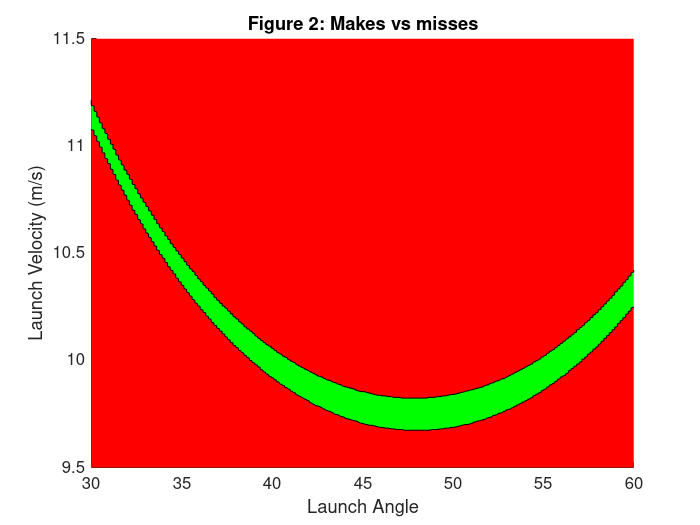

gen_contour_plot()

Note: because of the resolution of our data, the graph appears jittery and it seems as though the margin of error shrinks as the angle goes past 50 degrees or so, however if the staggered areas were smoothed out, then it would be more clear that the margin of error actually continues to increase. Unfortuneately, due to time and computational constraints, we were unable to further increase the resolution in our data. We have also included Figure 3 below to help make this trend clearer.

Figure 3 below graphs the size of the margin of error itself for each angle, where it becomes clear that the margin of error continues to grow as the angle increases. 

One effect of increasing launch angle is that the speed required to make the shot increases as well. Because it is less tiring and more consistent to shoot at a slower speed, the optimal angle to release the ball and the answer to our initial modeling question would be the smallest angle that still provides the greatest margin of error which is denotated with the red dot at 58.99 degrees and a margin of error of .1736 m/s.

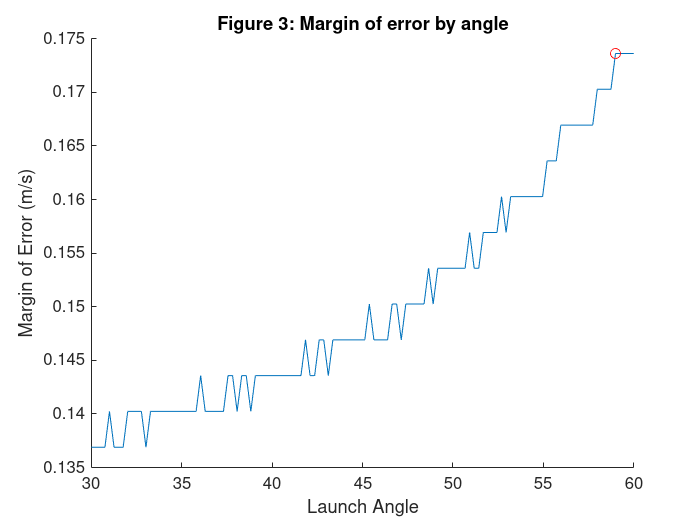

[angles, moes] = sweep_angle_moe();
figure; clf; hold on;
plot(angles, moes)
title('Figure 3: Margin of error by angle')
xlabel('Launch Angle')
ylabel('Margin of Error (m/s)')
plot(58.9916, .1736, 'ro')

Note: Once again, the small jitters in this graph are caused by not having high enough resolution in our shot speed parameter sweep. We have attempted to mitigate this by increasing the number of steps taken and reducing the range in which we sweep to squeeze in some extra density, but time and computation constraints have prevented us from attempting any further optimization.

### Verification

### Validation

 [T, U] = bball_trajectory(10, 57.45);
 figure; clf; hold on;
 plot(U(:, 1), U(:, 2))
 title('Flight path at optimal angle')
 xlabel('X position (m)')
 ylabel('Y position (m)')

## Interpretation

- How do the results answer the question?

- Do you think the answer is a good one? 

- What are the limitations of your model? 

- If you were going to continue developing your model, what next steps might you take? 

## Works Cited

“How to Choose a Basketball.” *Wilson Sporting Goods*, 10 May 2021, https://www.wilson.com/en-us/blog/basketball/how-tos/how-to-choose-a-basketball. 

Miller, Stuart, and Roger Bartlett. "The relationship between basketball shooting kinematics, distance and playing position." *Journal of sports sciences* 14.3 (1996): 243-253.

Okubo, Hiroki, and Mont Hubbard. *Identification of Basketball Parameters for a Simulation Model*. Elsevier Ltd., 21 Mar. 2010, https://www.sciencedirect.com/science/article/pii/S1877705810003991. 

“Rule No. 1: Court Dimensions – Equipment.” *RULE NO. 1: Court Dimensions – Equipment*, 1 Jan. 99AD, https://official.nba.com/rule-no-1-court-dimensions-equipment/. 

“What Is the Density of Air at STP?” *Machine Applications Corporation*, MAC Instruments, 7 May 2021, https://www.macinstruments.com/blog/what-is-the-density-of-air-at-stp/. 